障已知的实验,

clear
clc
 
ulogOBJ = ulogreader("log_0_2022-4-17-11-52-56.ulg");
msg = readTopicMsgs(ulogOBJ);

## known_logger

更换log文件后需要修改下面的数值，找到msg中对应的known_logger的序号是多少。

 
% 获取known_logger数据
known_logger = msg.TopicMessages{findtopic(msg.TopicNames, 'known_logger')};
% 生成相对时间
log_time = known_logger.timestamp;
time = seconds(log_time);
[time_size,~] = size(time);

% 读取数据
% tDes = known_logger.tdes;
iter = known_logger.iter;
chVDes = known_logger.chvdes;
pqd = known_logger.pqd;

% 处理数据
c = (0.0166);
l = (0.125);
M = ([ 1          1          1         1;
      -0.7071*l  -0.7071*l   0.7071*l  0.7071*l;
       0.7071*l  -0.7071*l  -0.7071*l  0.7071*l;
       c         -c          c        -c]);
Lambda = diag([0,1,1,1]);
tDes = zeros(time_size,4);
iter2 = zeros(time_size);
for i = 2:time_size
    [tDes(i,:),iter2(i),~] = caoptimal(chVDes(i,1),chVDes(i,2),chVDes(i,3),chVDes(i,4), 0, 0, M*Lambda, tDes(i-1,:));
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because the objective function

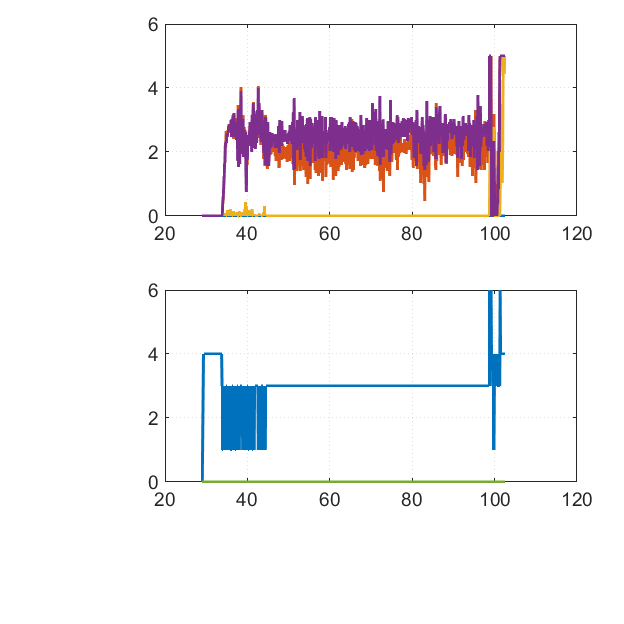

% 画图
figure(10)
clf
subplot(2,1,1)
plot(time,tDes)
subplot(2,1,2)
plot(time,iter2)

s = figure(11)

s =   Figure (11) - 属性:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 13.2000 13.2000]
       Units: 'centimeters'

  显示 所有属性


s.Position(4) = 15;
clf
subplot(5,1,1)
% plot(time,chVDes(:,1))
% hold on
plot(time,chVDes(:,2))
hold on
plot(time,chVDes(:,3))
hold on
plot(time,chVDes(:,4))
% ylabel('Rotor Force(N)','Interpreter',"latex")
% legend('#1','#2','#3','#4','Location',"north",'Orientation',"horizontal")
ylabel('(N$\cdot$m)','Interpreter',"latex")
legend('$\tau_p$','$\tau_q$','$\tau_r$','Location',"north",'Orientation',"horizontal",'Interpreter',"latex")
xlim([30,98])

subplot(5,1,2)
plot(time, iter,'--o','LineWidth',0.5)
legend('Iterations')
ylim([0,10])
xlim([30,98])

## vehicle_attitude

vehicle_attitude = msg.TopicMessages{35};
% 生成相对时间
time = seconds(vehicle_attitude.timestamp);

% 获取数据
[size_time,~] = size(time);
quate = vehicle_attitude.q;
angle = quat2dcm(quate);

primary_axis = zeros(size_time,3);
for i=1:size_time
    primary_axis(i,:) = angle(:,:,i)*[0,0,1]';
end

subplot(5,1,3)
plot(time,primary_axis(:,1))
hold on
plot(time,primary_axis(:,2))
hold on
plot(time,primary_axis(:,3))
ylabel('$\mathbf{n}_3$','Interpreter',"latex")
legend('$h_1$','$h_2$','$h_3$','Orientation',"horizontal",'Interpreter',"latex")
xlim([30,98])

## sensor_combined

sensor_combined = msg.TopicMessages{23};
% 生成相对时间
time = seconds(sensor_combined.timestamp);

% 获取数据 
gyro = sensor_combined.gyro_rad;


subplot(5,1,4)
plot(time, gyro)
legend('$p$','$q$','$r$','Orientation',"horizontal",'Interpreter',"latex")
ylabel('(rad/s)','Interpreter',"latex")
xlim([30,98])

## input_rc

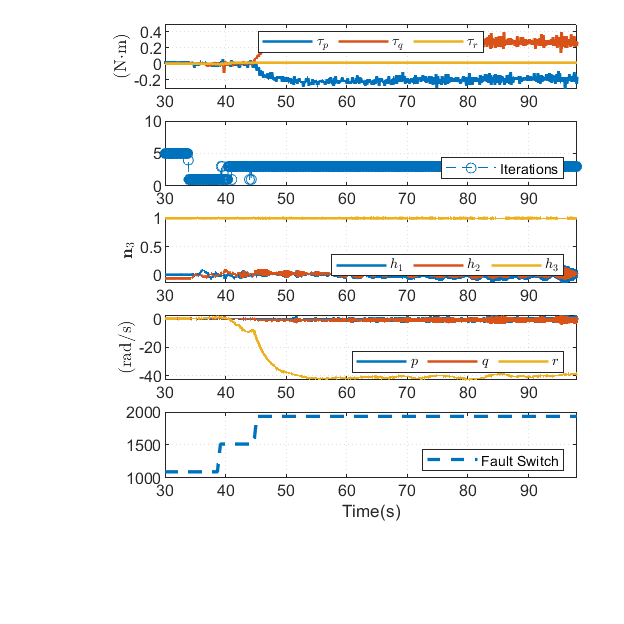

input_rc = msg.TopicMessages{11};
% 生成相对时间
log_time = input_rc.timestamp;
time = seconds(log_time);
[sample_count,~] = size(log_time);
% 获取数据
rc = input_rc.values;

subplot(5,1,5)
% plot(time,rc(:,1),'LineWidth',1)
% hold on
% plot(time,rc(:,2),'LineWidth',1)
% hold on
% plot(time,rc(:,3),'--')
% hold on
% plot(time,rc(:,4),'--')
% hold on
% plot(time,rc(:,5),'--')
% hold on
plot(time,rc(:,6),'--','LineWidth',2)
legend('Fault Switch','Location',"best",'Orientation',"horizontal")
xlabel('Time(s)')
xlim([30,98])